%cleaning workspace
clear;

% Load dataset
load Dataset_task2.mat;
%Dataset presenta dati mancanti o errati e colonna 19 duplicata di 18
short_matrix_no_id(:,19) = [];
short_matrix_no_id = fillmissing(short_matrix_no_id,"knn");
%split type of day in 3 boolean column
%[sun=0, rain=1, snow=2]
type_of_day = dummyvar(short_matrix_no_id(:, 16) + 1);
short_matrix_no_id(:,16) = [];
%concat type of day at the end of the dataset
short_matrix_no_id = [short_matrix_no_id, type_of_day];

%NORMALIZE DATA
short_matrix_no_id(:,[2:5,9:14,17]) = normalize(short_matrix_no_id(:,[2:5,9:14,17]), 'range', [0, 1]);
%short_matrix_no_id(:,[2:4]) = normalize(short_matrix_no_id(:,[2:4]), 'range', [0, 1]);
%short_matrix_no_id(:,[5,9:15,18]) = zscore(short_matrix_no_id(:,[5,9:15,18]));

%BUS LINE
bus_line = short_matrix_no_id(:,[1, 2:6, 8:9, 15, 16, 18:20]);

%Vehicle ID
vehicle_id = short_matrix_no_id(:,[1, 6:8, 11:15, 17]);

%driver id
driver_id = short_matrix_no_id(:, [1, 6, 8, 15]);

% Calcolo del numero di cluster
unique_driver = unique(short_matrix_no_id(:,8),"rows"); %229 istanze
unique_vehicle = unique(short_matrix_no_id(:,6),"rows"); %105 istanze
unique_line = unique(short_matrix_no_id(:,1),"rows"); % 87 istanze


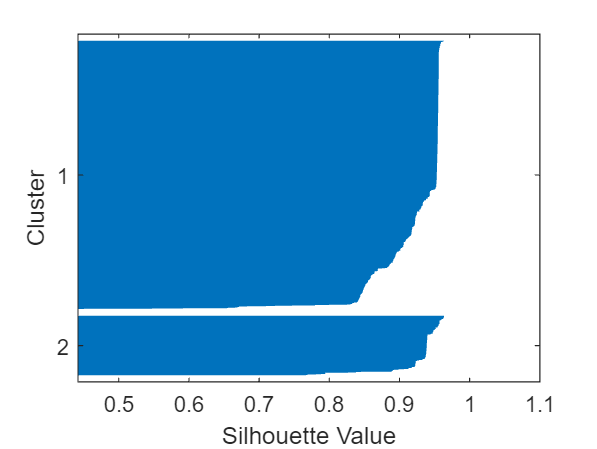

ans = 0.9256

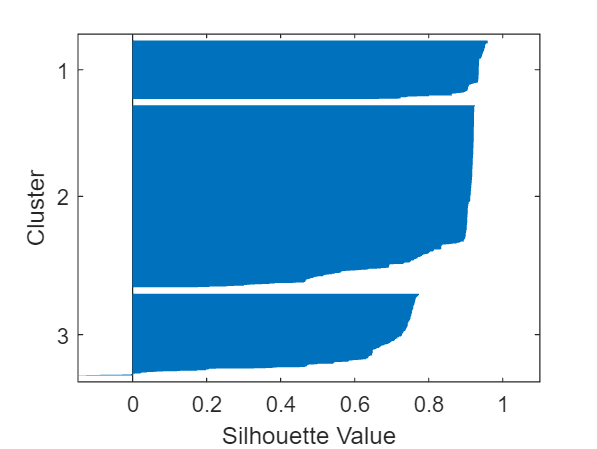

ans = 0.8097

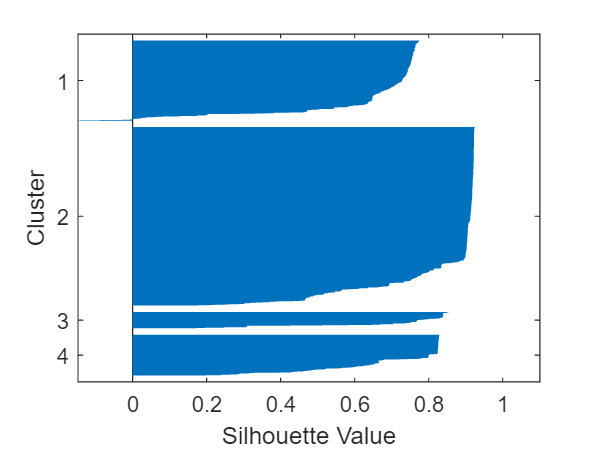

ans = 0.7702

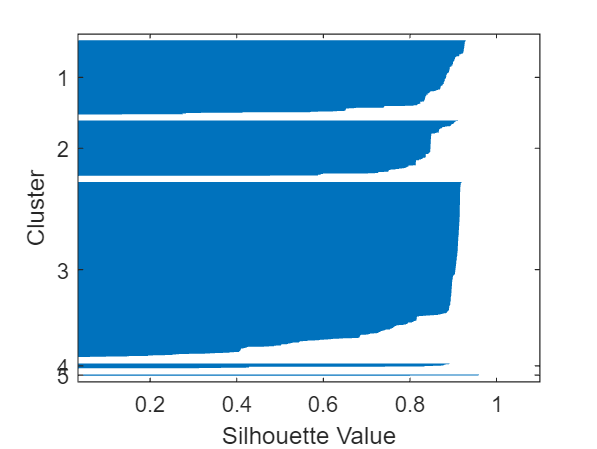

ans = 0.8356

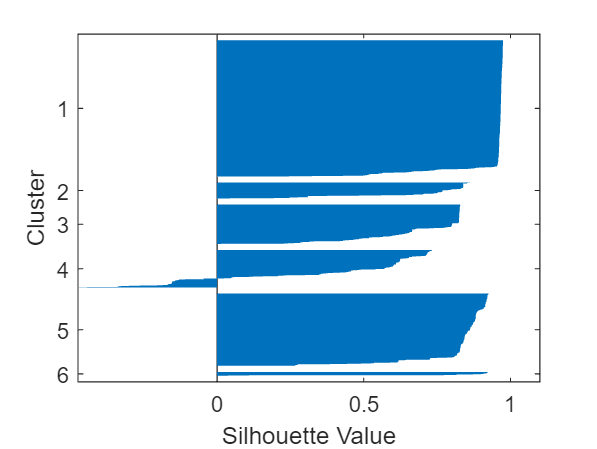

ans = 0.8014

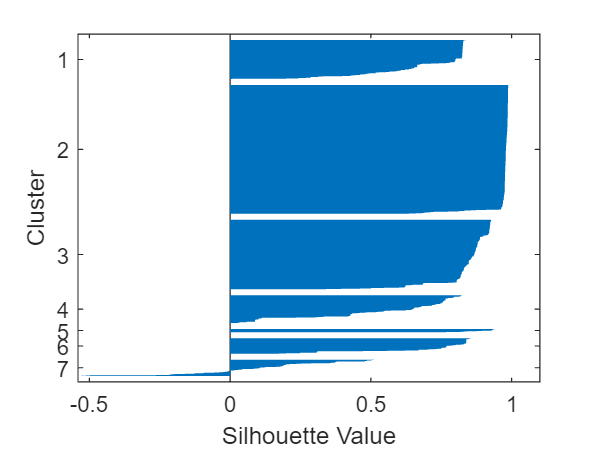

ans = 0.8060

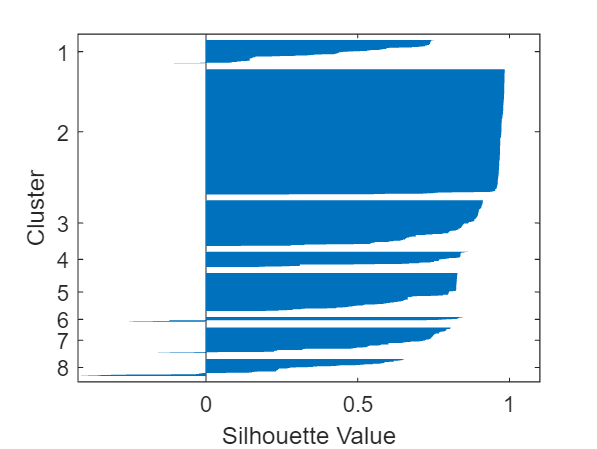

ans = 0.7761

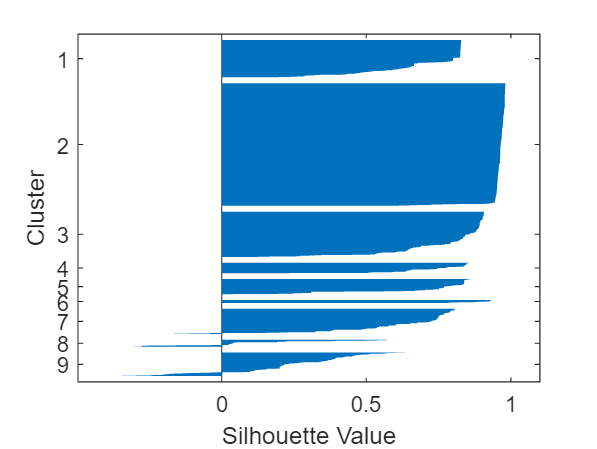

ans = 0.7673

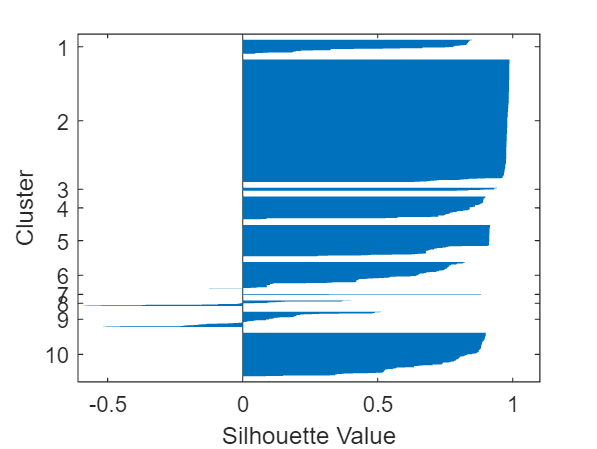

ans = 0.7811

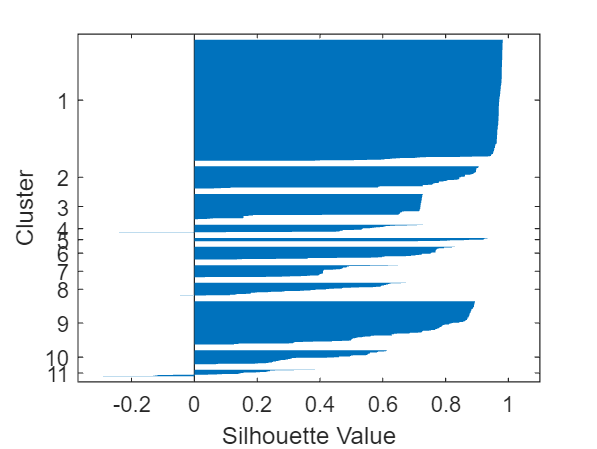

ans = 0.7602

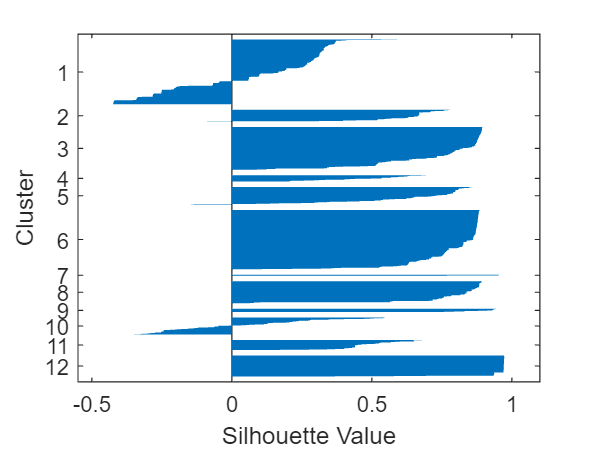

ans = 0.5465


% Range of number of clusters
k_values = 2:12;

% Initialize array to store percentage variance for each matrix
variance_pct_driver = zeros(size(k_values));
variance_pct_vehicle = zeros(size(k_values));
variance_pct_busline = zeros(size(k_values));
mean_silhouette_scores = [];
% Perform k-means clustering for each number of clusters on driver_id
for i = 1:length(k_values)
    k = k_values(i);
    
    % Run k-means clustering on driver_id
    [idx_driver, centroids, sumd] = kmeans(driver_id, k);
    
    % Calculate total variance
    total_variance = sum(sumd);
    
    % Calculate percentage variance for current number of clusters
    variance_pct_driver(i) = (total_variance - sumd(1)) / total_variance * 100;
    figure;
    sil_scores = silhouette(driver_id,idx_driver);
    silhouette(driver_id,idx_driver);

    mean(sil_scores)
    
end

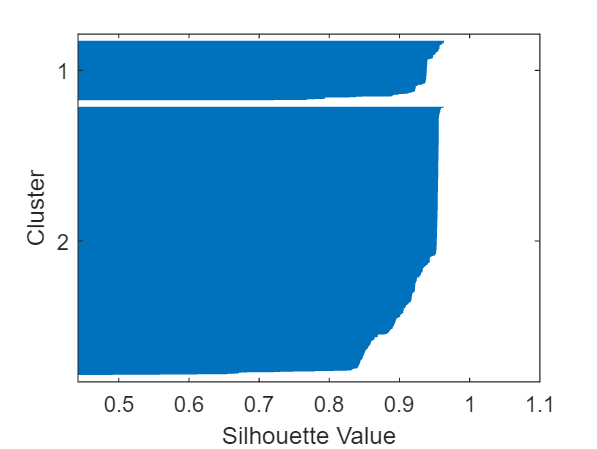

ans = 0.9256

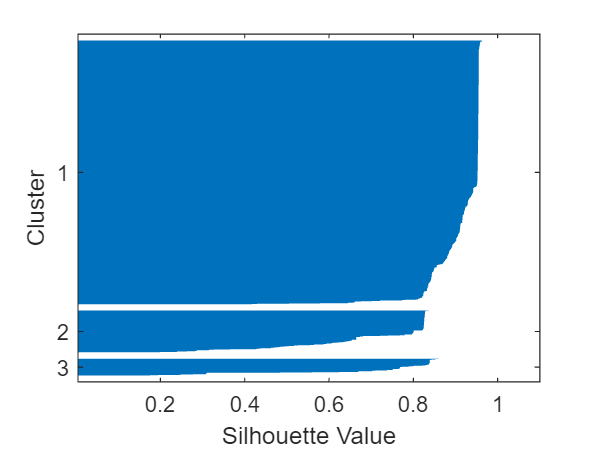

ans = 0.8810

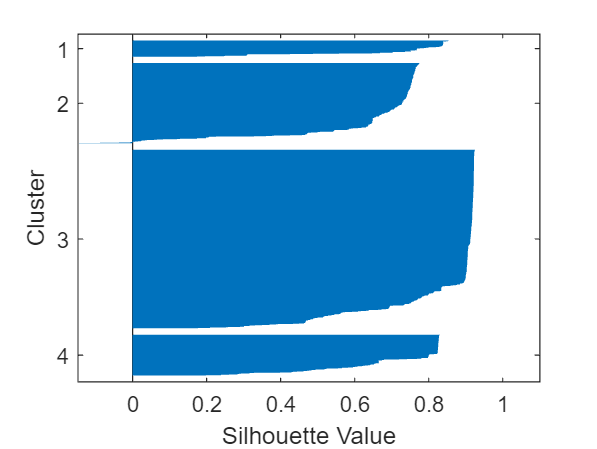

ans = 0.7702

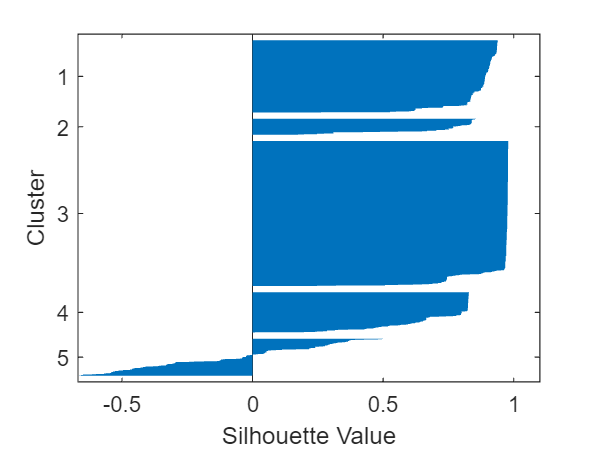

ans = 0.7635

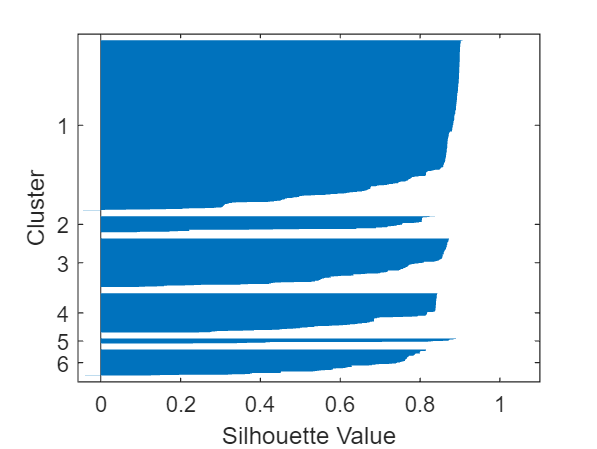

ans = 0.7660

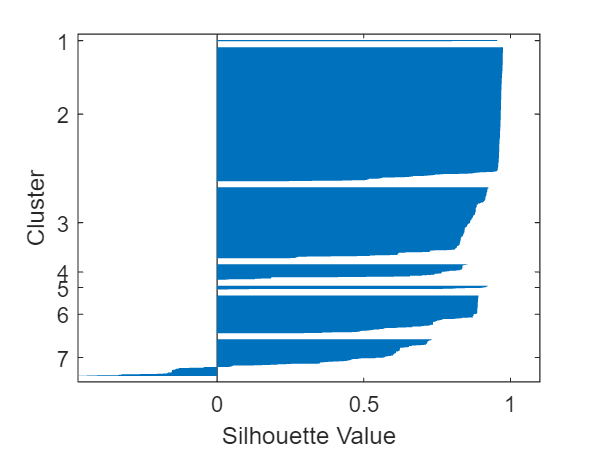

ans = 0.8119

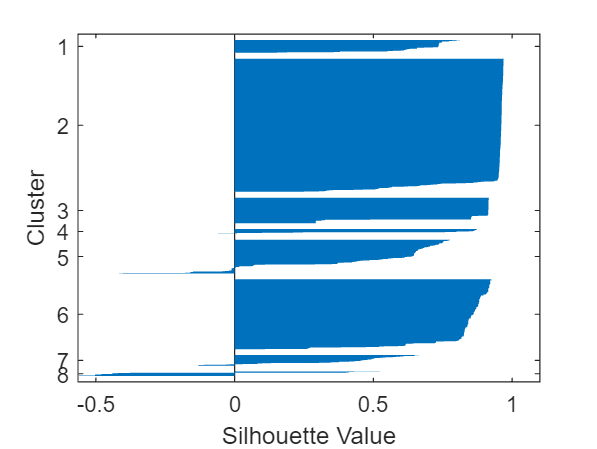

ans = 0.7892

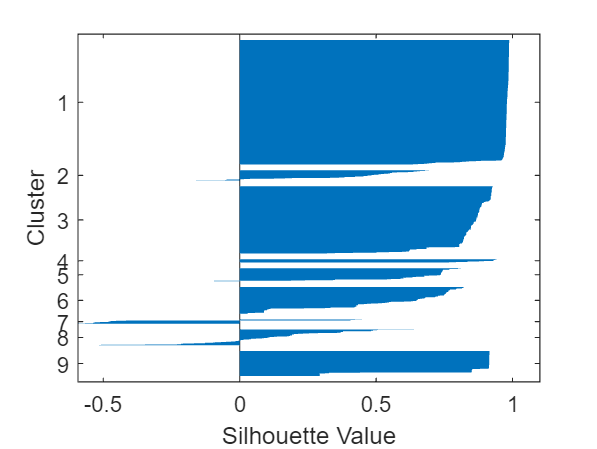

ans = 0.7879

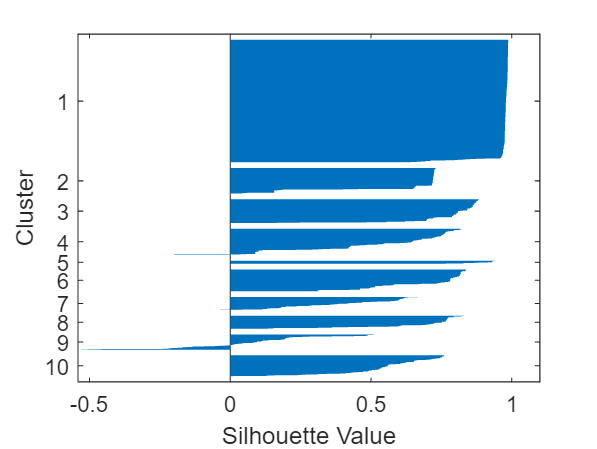

ans = 0.7434

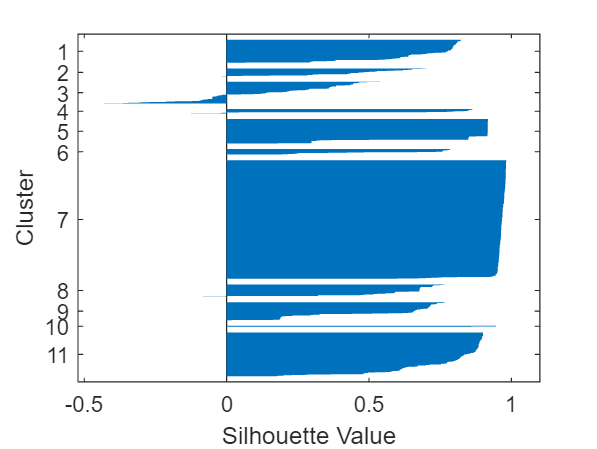

ans = 0.7621

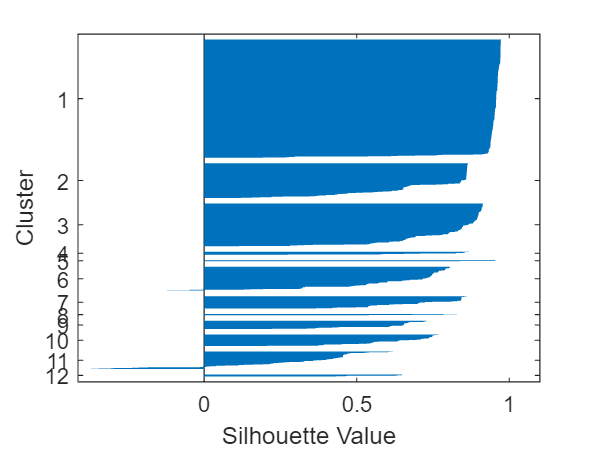

ans = 0.7846


% Perform k-means clustering for each number of clusters on vehicle_id
for i = 1:length(k_values)
    k = k_values(i);
    
    % Run k-means clustering on vehicle_id
    [idx_vehicle, centroids, sumd] = kmeans(vehicle_id, k);
    
    % Calculate total variance
    total_variance = sum(sumd);
    
    % Calculate percentage variance for current number of clusters
    variance_pct_vehicle(i) = (total_variance - sumd(1)) / total_variance * 100;
    figure;
    sil_scores = silhouette(vehicle_id,idx_vehicle);
    silhouette(vehicle_id,idx_vehicle);
    mean(sil_scores)
    
end

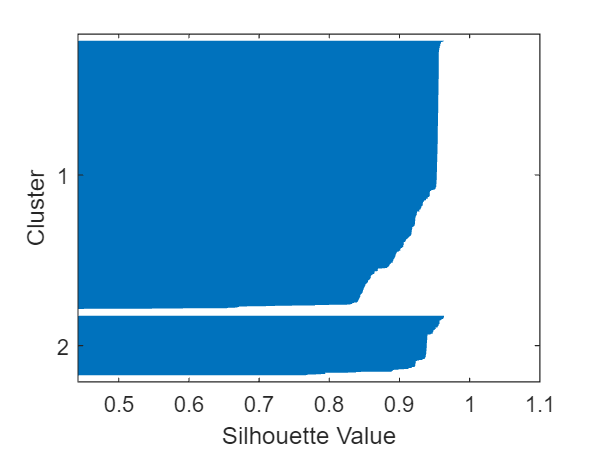

ans = 0.9256

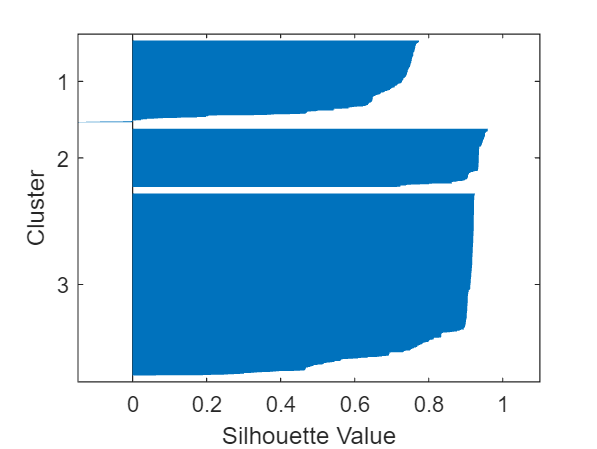

ans = 0.8097

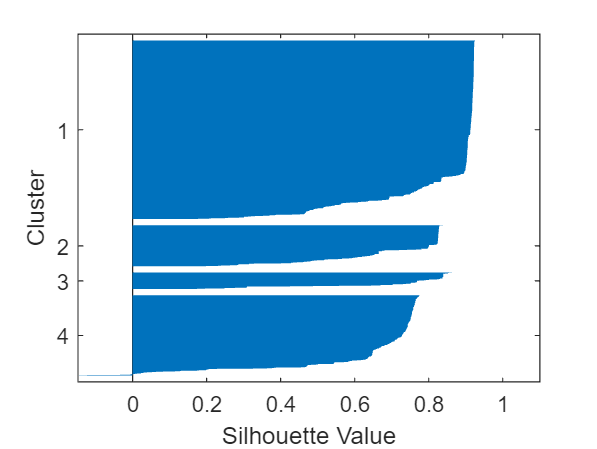

ans = 0.7702

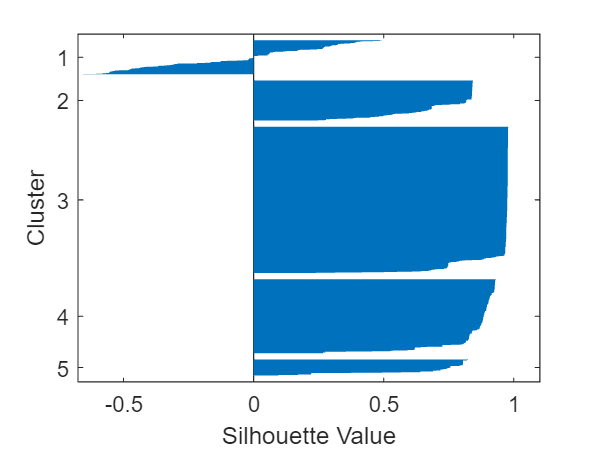

ans = 0.7712

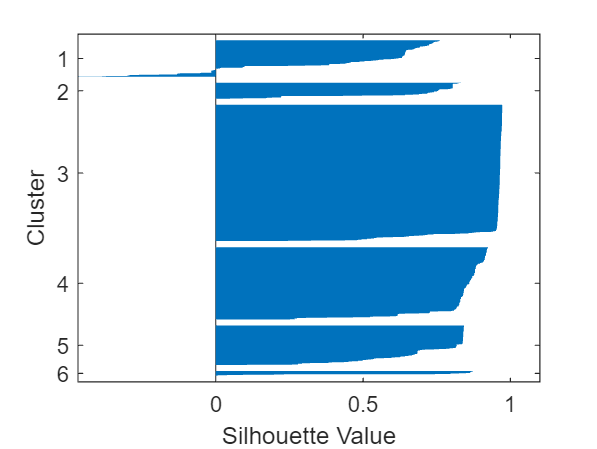

ans = 0.8052

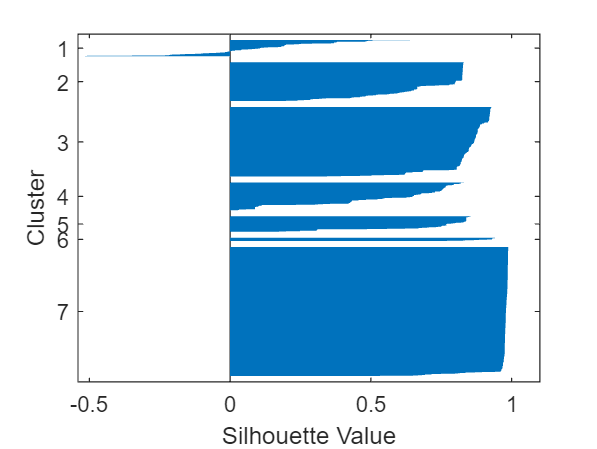

ans = 0.8060

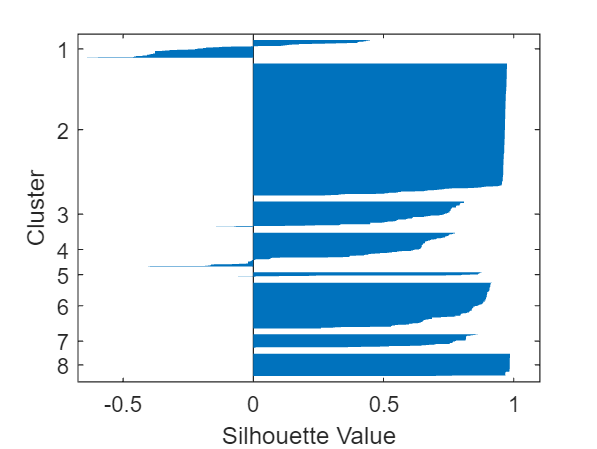

ans = 0.7600

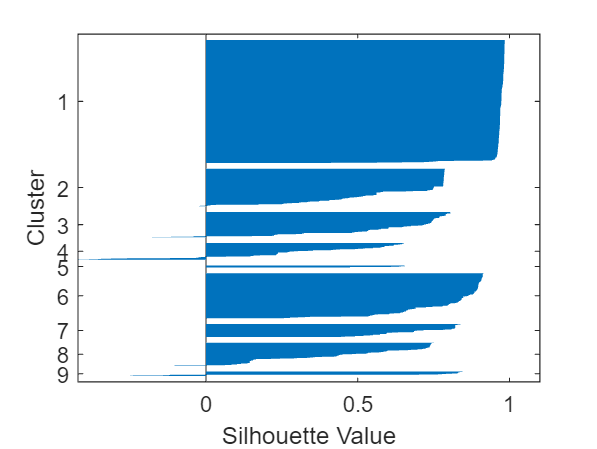

ans = 0.7653

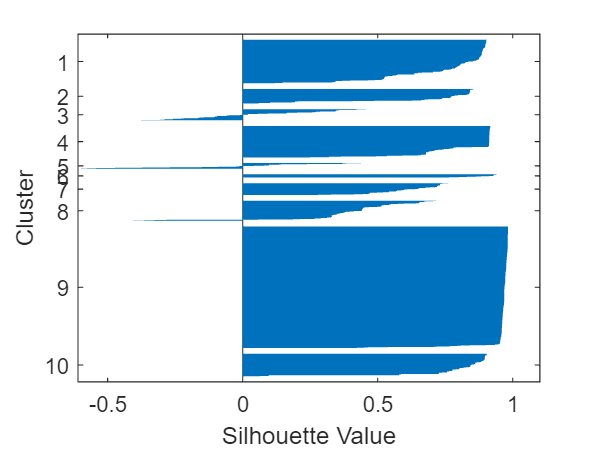

ans = 0.7804

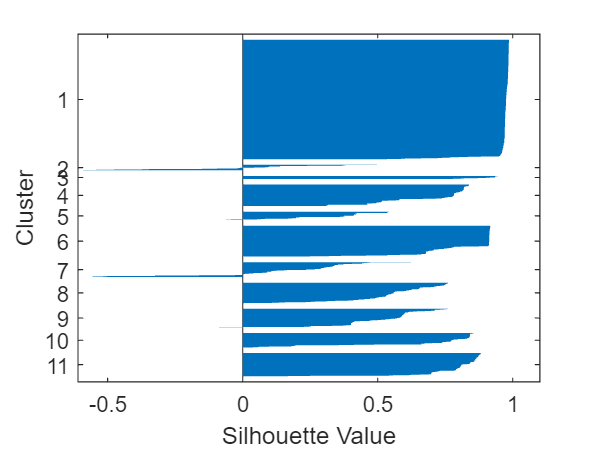

ans = 0.7599

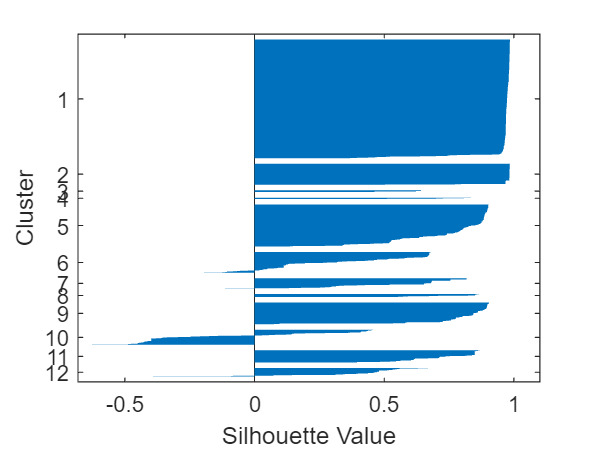

ans = 0.7638


% Perform k-means clustering for each number of clusters on bus_line
for i = 1:length(k_values)
    k = k_values(i);
    
    % Run k-means clustering on bus_line
    [idx_line,centroids, sumd] = kmeans(bus_line, k);
    
    % Calculate total variance
    total_variance = sum(sumd);
    
    % Calculate percentage variance for current number of clusters
    variance_pct_busline(i) = (total_variance - sumd(1)) / total_variance * 100;
    figure;
    sil_scores = silhouette(bus_line,idx_line);
    silhouette(bus_line,idx_line);
    mean(sil_scores)
end

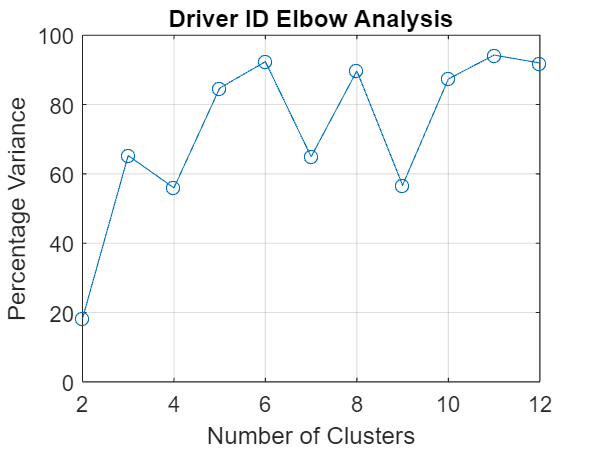


% Plot elbow curves for each matrix separately
figure;
plot(k_values, variance_pct_driver, '-o');
xlabel('Number of Clusters');
ylabel('Percentage Variance');
title('Driver ID Elbow Analysis');
grid on;

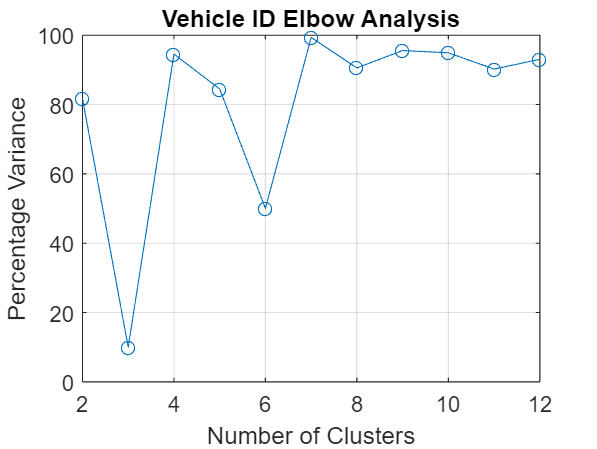


plot(k_values, variance_pct_vehicle, '-o');
xlabel('Number of Clusters');
ylabel('Percentage Variance');
title('Vehicle ID Elbow Analysis');
grid on;

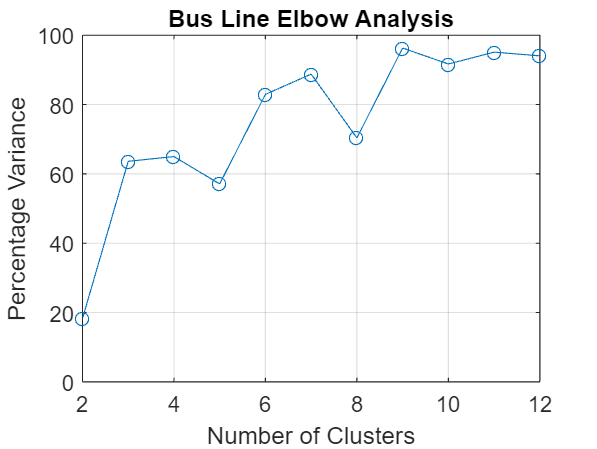


plot(k_values, variance_pct_busline, '-o');
xlabel('Number of Clusters');
ylabel('Percentage Variance');
title('Bus Line Elbow Analysis');
grid on;

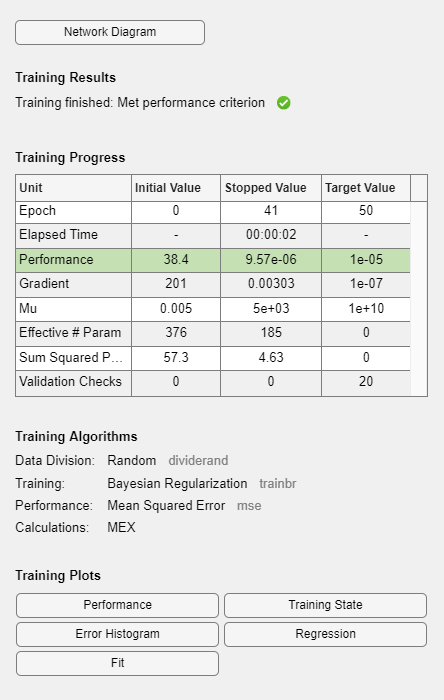

idx_line = kmeans(bus_line, 5);
idx_vehicle = kmeans(vehicle_id, 6);
idx_driver = kmeans(driver_id, 5);

% Assign a new ID to each cluster
cluster_line_ids = (1:5)';
cluster_vehicle_ids = (1:6)';
cluster_driver_ids = (1:5)';


% Assign a new ID to each cluster
new_ids_line = cluster_line_ids(idx_line);
new_ids_vehicle = cluster_vehicle_ids(idx_vehicle);
new_ids_driver = cluster_driver_ids(idx_driver);

% Replace the original IDs in the dataset with the new IDs
short_matrix_no_id = [short_matrix_no_id, new_ids_line new_ids_vehicle new_ids_driver];

X = short_matrix_no_id;
X(:, [1,6,8]) = [];
Y = short_matrix_no_id(:,15);

% Train neural network
avg_accuracy = 0;
avg_MSE = 0;
avg_COV = 0;
n_cycle=50;

for i = 1:n_cycle
    % Split data into training and testing sets
    train_ratio = 0.5;
    train_size = round(train_ratio*size(X,1));
    train_idx = randperm(size(X,1),train_size);
    test_idx = setdiff(1:size(X,1),train_idx);
    X_train = X(train_idx,:);
    Y_train = Y(train_idx,:);
    X_test = X(test_idx,:);
    Y_test = Y(test_idx,:);

    % Define neural network
    input_size = size(X_train,2);
    output_size = 1;
    hidden_size = 15;
    net = fitnet(hidden_size);
    net.trainFcn = 'trainbr'; % Bayesian regulation algorithm
    net.divideFcn = 'dividerand'; % Random division of data into training and validation sets
    net.divideParam.trainRatio = 0.5; % Training set proportion
    net.divideParam.valRatio = 1 - net.divideParam.trainRatio; % Validation set proportion
    net.divideParam.testRatio = 0; % No testing set
    net.trainParam.max_fail = 20; % Maximum validation failures
    net.trainParam.epochs = 50; % Maximum number of epochs
    net.trainParam.goal = 1e-5; % Training goal
    net.performFcn = 'mse'; % Mean squared error performance function
    net.plotFcns = {'plotperform','plottrainstate','ploterrhist', ...
        'plotregression', 'plotfit'};
    %train
    [net,tr] = train(net,X_train',Y_train');
    
    % Test neural network
    Y_pred = net(X_test');
    
    % Calculate the covariance error
    cov_error = sum(sum((cov(Y_pred) - Y_test).^2));
    acc = mean(abs(Y_pred-Y_test')<0.02);

    avg_accuracy = avg_accuracy + acc;
    avg_MSE = avg_MSE + mse(net,Y_pred,Y_test');
    avg_COV = avg_COV + cov_error;
end

avg_accuracy = avg_accuracy/n_cycle;
avg_COV = avg_COV/n_cycle;
avg_MSE = avg_MSE/n_cycle;
disp('AVG ACCURACY: '+ avg_accuracy);

    66    87    72    33    66    68    68    86    83    66    68    90    59    33



disp('AVG MSE: '+ avg_MSE);

   65.0000   86.0000   71.0000   32.0000   77.0000   83.0000   69.0000   58.0000   32.0000



disp('AVG COV: '+ avg_COV);

   1.0e+04 *

    3.7938    3.7959    3.7944    3.7905    3.7940    3.7952    3.7959    3.7931    3.7905




% Display the covariance matrix
cov(Y_pred,Y_test)

ans =     6.1076    6.1083
    6.1083    6.1090
